Pstar = @(x) exp(-x.^2) .* (2 + sin(x*5) + sin(x*2))

Pstar = function_handle with value:
    @(x)exp(-x.^2).*(2+sin(x*5)+sin(x*2))


N = 100

N =    100


proposalWidth = 1

proposalWidth =      1


L = 6

L =      6


Pstar = function_handle with value:
    @(f)f.^(a+nH-1).*(1-f).^(N-nH+b-1)*nchoosek(N,nH)


N =         1000


proposalWidth =    0.025000000000000


L =      1


X =    0.134897098869205
   0.134897098869205
   0.134897098869205
  -1.314200193969534
  -0.980689360903729
  -0.589335756470828
  -0.137656337542590
  -0.137656337542590
   0.046032758319352
   0.046032758319352
   0.046032758319352
   0.046032758319352
   0.501062314763686
   0.501062314763686
   0.166175375799639
   0.166175375799639
   0.166175375799639
  -0.951463307465569
   0.309195401655327
   0.309195401655327
   0.241329848112640
   0.046108650213885
   0.046108650213885
   0.046108650213885
   0.069154274638990
   0.120444630487765
   0.120444630487765
   0.120444630487765
   0.120444630487765
   0.120444630487765
   0.120444630487765
   0.303671893489202
  -0.726095650077419
   0.223126181053604
   0.223126181053604
   0.358301123153059
   0.358301123153059
   0.619707447208442
   0.619707447208442
   0.457369774404614
   0.311315140073088
   0.311315140073088
   0.311315140073088
   0.311315140073088
   0.311315140073088
   0.311315140073088
   0.311315140073088
   0.1190

X = MHsimple

X =   -0.049055328169913
  -0.049055328169913
   0.411564476503113
   0.411564476503113
   0.411564476503113
   0.305009324937473
   0.305009324937473
   0.305009324937473
   0.305009324937473
   0.178997964821039
   0.475169148830262
   0.475169148830262
   0.345241518339995
   0.465573088656839
   0.465573088656839
   0.465573088656839
   0.465573088656839
   0.519067896230607
   0.519067896230607
   0.286883034454980
   0.286883034454980
   0.286883034454980
   0.286883034454980
   0.286883034454980
   0.154411442277247
   0.154411442277247
   0.154411442277247
   0.154411442277247
   0.154411442277247
   0.718049026684271
   0.718049026684271
   0.718049026684271
   0.718049026684271
   0.718049026684271
   0.319885919529191
   0.319885919529191
   0.319885919529191
   0.319885919529191
   0.319885919529191
   0.319885919529191
   0.319885919529191
   0.319885919529191
   0.319885919529191
   0.453912541348099
   0.453912541348099
   0.453912541348099
   0.453912541348099
   0.4539

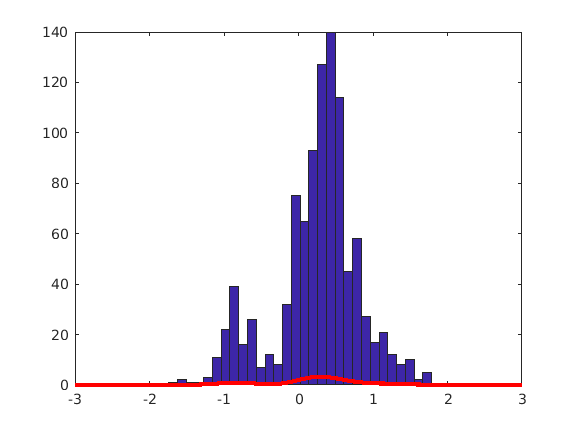

% PLotting the function with the posterior
xValues = -3:0.01:3;
figure(1); clf;
hist(X, 30, 'facealpha', 0.2, 'EdgeColor','w');

hold on;
plot(xValues, Pstar(xValues), 'Color', 'r', 'LineWidth', 3)

a = 12;
b = 12;
nH = 12;
N = 50;
Pstar = @(f) f .^ (a + nH - 1) .* (1 - f).^(N - nH + b-1) %* nchoosek(N, nH)

Pstar = function_handle with value:
    @(f)f.^(a+nH-1).*(1-f).^(N-nH+b-1)


%N = 1000
proposalWidth = 0.025

proposalWidth =    0.025000000000000


L = 1

L =      1


xInit = 0.5

xInit =    0.500000000000000


rng('default');
X = MetropolisSampling(10000, L, proposalWidth, xInit, Pstar);

X

X =    0.334441181460615
   0.307106058240808
   0.310974552530226
   0.286677826704137
   0.291980447969573
   0.286962683062416
   0.308896215104244
   0.308896215104244
   0.305964376181557
   0.312021250259634
   0.292427083068366
   0.292280235295624
   0.305945060873049
   0.305945060873049
   0.318757521158419
   0.352725391341421
   0.353624472220916
   0.308501261141684
   0.299136461041456
   0.340973634446783
   0.322307576676348
   0.347999175546845
   0.339101861531867
   0.319027248976349
   0.320399146264480
   0.312124672548222
   0.331985263313433
   0.323827344344536
   0.323827344344536
   0.313367110166722
   0.283552324208222
   0.322590722660803
   0.339658428050531
   0.353576174515875
   0.380036650125848
   0.381334763252290
   0.371988537929040
   0.319419571907764
   0.353437491068672
   0.343162449294875
   0.354144432258406
   0.352956865475479
   0.364304678602667
   0.358764246013643
   0.341782673457040
   0.358897918584410
   0.394605344425409
   0.3631

aNew = a + nH-1

aNew =     23


bNew = N - nH + b - 1

bNew =     49


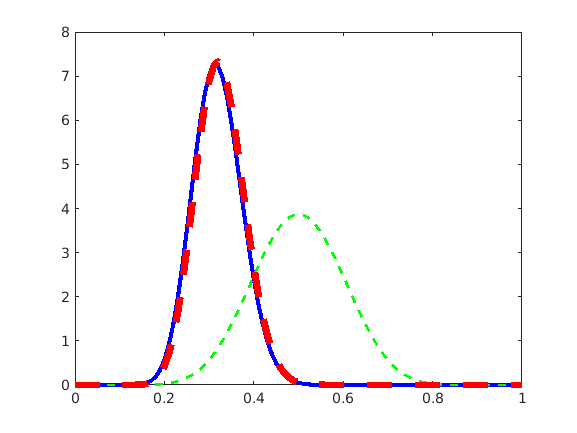

% PLotting the function with the posterior
xValues = 0:0.01:1;
figure(1); clf;
%hist(X, 30, 'facealpha', 0.2, 'EdgeColor','w');


% Posterior: Beta(aNew, bNew) = Beta(23, 49)
plot(xValues, betapdf(xValues, aNew, bNew), 'Color', 'b', 'LineWidth', 3)
hold on; 
% Prior : Beta(a = 12, b = 12)
plot(xValues, betapdf(xValues, a, b), 'Color', 'g', 'LineWidth', 2, 'LineStyle', '--')
hold on;
normalizedPosterior = Pstar(xValues) / beta(a + nH, N - nH + b);
plot(xValues, normalizedPosterior, 'Color', 'r', 'LineWidth', 5, 'LineStyle', '--')